#### **Question-01:** Construct signals: 

#### (i) x(n)= $\delta$(n) 

#### (ii) x(n)= $\delta$(n-5) and 

#### (iii) x(n)= $\delta$(n+5) 

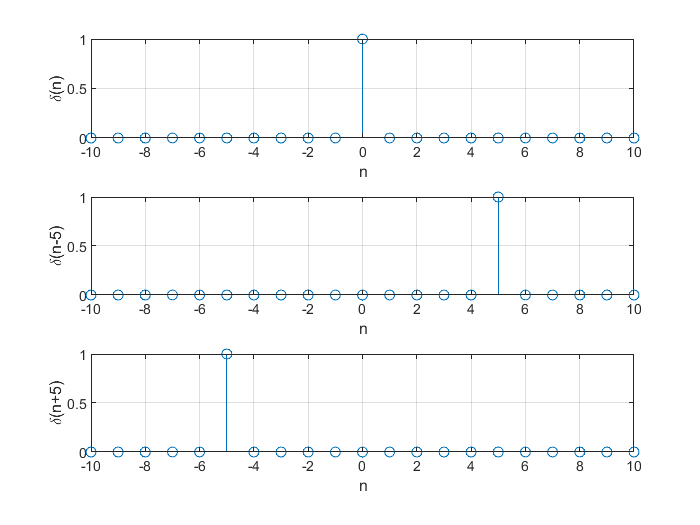

clc;close all;
n=-10:10; 
x=[n==0];
figure;
subplot(3,1,1);
stem (n,x); 
xlabel('n');
ylabel('\delta(n)'); 
grid on
x1=[(n-5)==0];
subplot(3,1,2);
stem (n,x1);
xlabel('n');
ylabel('\delta(n-5)'); 
grid on
x2=[(n+5)==0];
subplot(3,1,3);
stem (n,x2);
xlabel('n');
ylabel('\delta(n+5)'); 
grid on

#### Question-02: Construct signals: 

#### (i) x(n) = u(n), 

#### (ii) x(n) = u(n+10) and 

#### (ii) x(n) = u(n-10) 

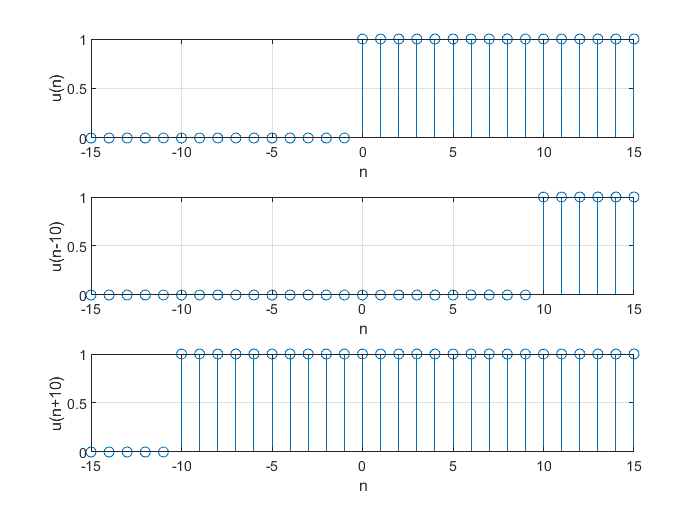

clc; close all;
n=-15:15;
x=[n>=0];
figure;
subplot(3,1,1);
stem (n,x);
xlabel('n');
ylabel('u(n)'); 
grid on
x1=[(n-10)>=0];
subplot(3,1,2);
stem (n,x1); 
xlabel('n');
ylabel('u(n-10)'); 
grid on
x2=[(n+10)>=0];
subplot(3,1,3);
stem (n,x2);
xlabel('n');
ylabel('u(n+10)'); 
grid on

#### Question-03: Construct signals: 

#### (i) x(n) = r(n), 

#### (ii) x(n) = r(n+5) and 

#### (iii) x(n) = r(n-5)

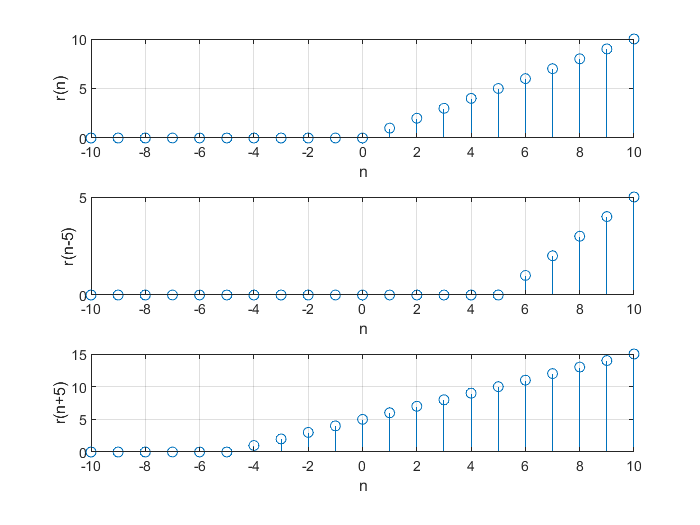

clc; close all
n=-10:10;
x=n.*[n>=0];
figure;
subplot(3,1,1);
stem (n,x);
xlabel('n');
ylabel('r(n)'); 
grid on
x1=(n-5).*[(n-5)>=0];
subplot(3,1,2);
stem (n,x1);
xlabel('n');
ylabel('r(n-5)'); 
grid on
x2=(n+5).*[(n+5)>=0];
subplot(3,1,3);
stem (n,x2);
xlabel('n');
ylabel('r(n+5)'); 
grid on

#### Question-04: Construct signals: 

#### (i) x(n) = e(n+10) and 

#### (ii) x(n) = e(n-10) for a = 0.8

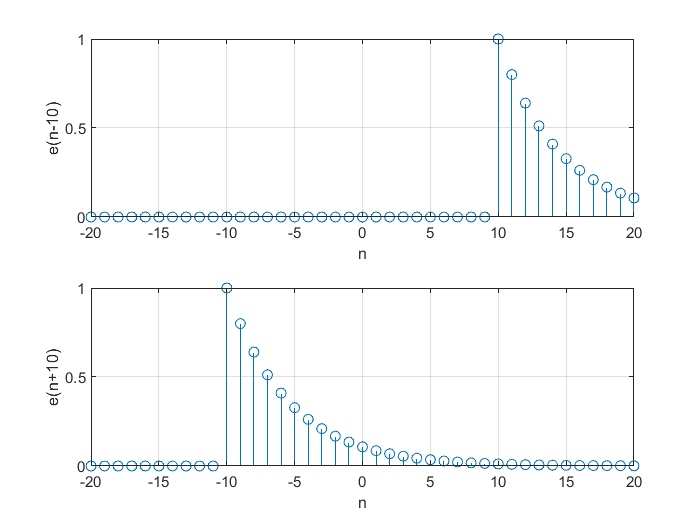

clc; close all
n=-20:20;
a=0.8;
figure;
x1=(a.^(n-10)).*[(n-10)>=0];
subplot(2,1,1)
stem (n,x1);
xlabel('n');
ylabel('e(n-10)');
grid on
x2=(a.^(n+10)).*[(n+10)>=0];
subplot(2,1,2)
stem (n,x2);
xlabel('n');
ylabel('e(n+10)'); 
grid on

#### Question-05: Let x(n) = 2n+1 for -3 ≤ n ≤3. Construct a signal y(n) = 3x(n). 

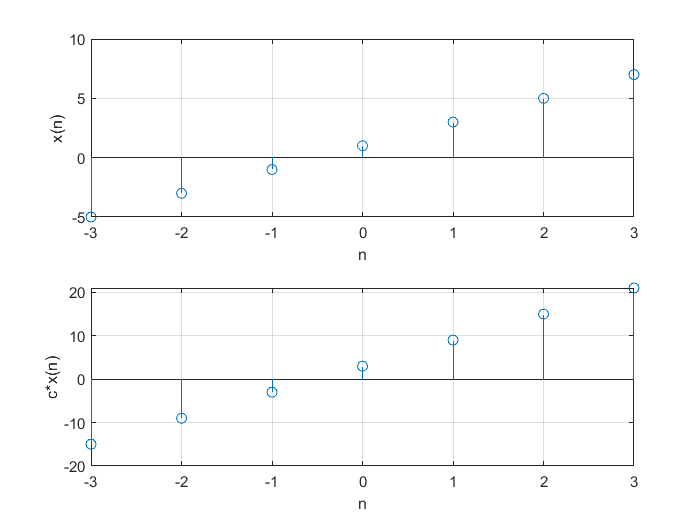

clc;clear all; 
n=-3:3; 
x=2*n+1;
c=3;
[yc,nc] = ampscal(x,n,c);
figure;
subplot(2,1,1)
stem(n,x);
xlabel('n');
ylabel('x(n)'); 
grid on
subplot(2,1,2)
stem(nc,yc);
xlabel('n');
ylabel('c*x(n)'); 
grid on

#### Question-06: Let x(n) = 2n+1 for -3 ≤ n ≤3. Construct a signals y1(n) = x(n-5) and y2(n) = x(n+5). 

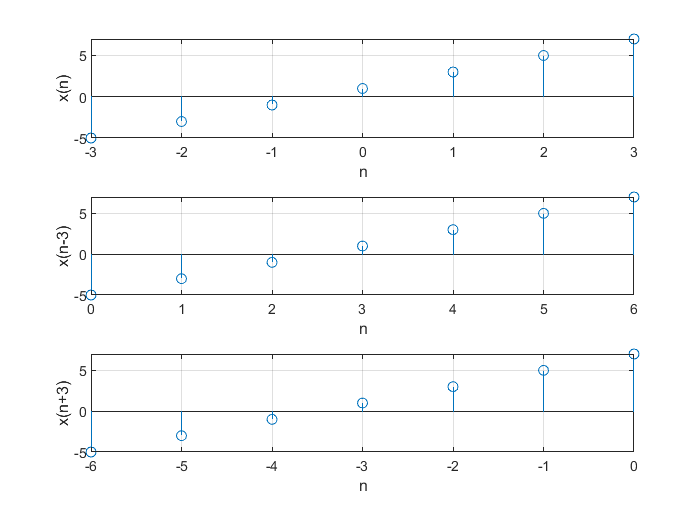

clc; clear all; 
n=-3:3;
x=2*n+1; 
c1=3;
c2=-3;
[x1,n1]=sigshift(x,n,c1);
[x2,n2]=sigshift(x,n,c2); 
figure;
subplot(3,1,1); 
stem(n,x);
xlabel('n');
ylabel('x(n)'); 
grid on
subplot(3,1,2); 
stem(n1,x1);
xlabel('n');
ylabel('x(n-3)'); 
grid on
subplot(3,1,3); 
stem(n2,x2);
xlabel('n');
ylabel('x(n+3)'); 
grid on

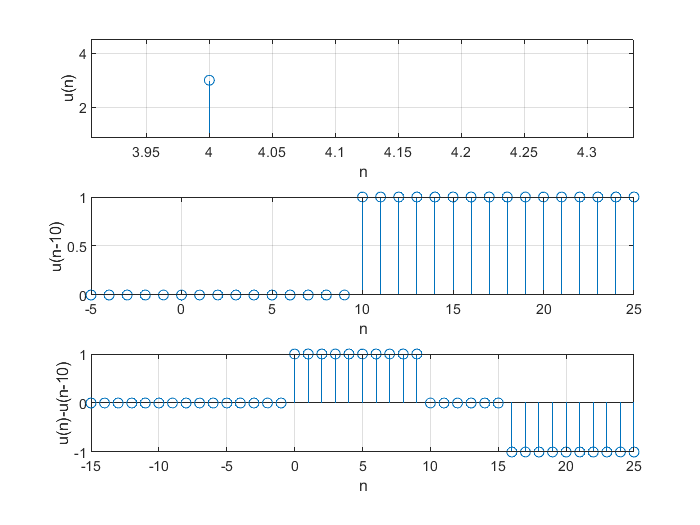

clc;close all;
n=-15:15;
x=[n>=0];
[x2,n2]=sigshift(x,n,10); 
[xa,na]=sigadd(x,n,-x2,n2); 
figure;
subplot(3,1,1)
stem(n1,x1);xlabel('n');ylabel('u(n)'); grid on
subplot(3,1,2)
stem(n2,x2);xlabel('n');ylabel('u(n-10)'); grid on
subplot(3,1,3)
stem(na,xa);xlabel('n');ylabel('u(n)-u(n-10)'); grid on

function [y,n]=ampscal(x,n,c)
y=c.*x;
end

function [y,n]=sigshift(x,m,n0)
n=m+n0;
y=x;
end

function [y,n]=sigadd(x1,n1,x2,n2)
min_n=min(min(n1),min(n2));
max_n=max(max(n1),max(n2));
n=min_n:max_n;
y1=zeros(1,length(n));
y2=y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;
y=y1+y2;
end